# Practice 1

load carsmall;
% cars = importdata('carsmall.mat')

What are the mean, standard deviation and median of Acceleration?

mean(Acceleration)

ans = 15.0280

std(Acceleration)

ans = 3.3485

median(Acceleration)

ans = 15.1500

%quantile(Acceleration, .5)

From MPG (Miles Per Gallon) consumption calculate LPHKM (Liter Per Hundred KiloMeters), if

- 1 gallon = 3.79 liter

- 1 mile = 1.61 kilometers

Hint: element-by-element oprations are

LPHKM = 1./(MPG * 1.61 / 3.79)*100;

Round it to 1 decimal place:

LPKHM = round(LPHKM,1);

Which car has the highest consumption? Use the 'Model' character variable to get the name of the car.

ind = find(LPKHM == max(LPKHM));
Model(ind,:)

ans = 'ih 1200d                         '

Count the number of cars with LPKHM > 15 liter. Whats the relative frequency of them?

sum(LPKHM > 15)

ans = 20

sum(LPKHM > 15) / length(LPKHM)

ans = 0.2000

Investigate consumption, conditional to number of cylinders with a boxplot.

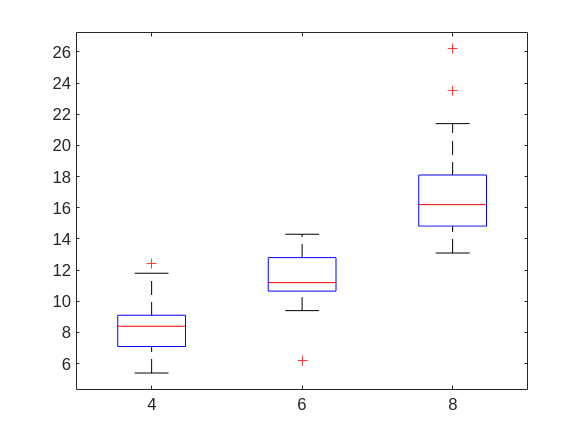

boxplot(LPKHM, Cylinders)

Plot a probability histogram on Acceleration. Does it look normally distributed? 

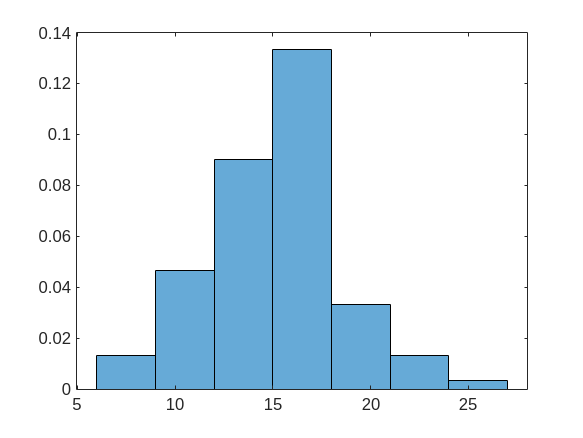

histogram(Acceleration,'Normalization','pdf')

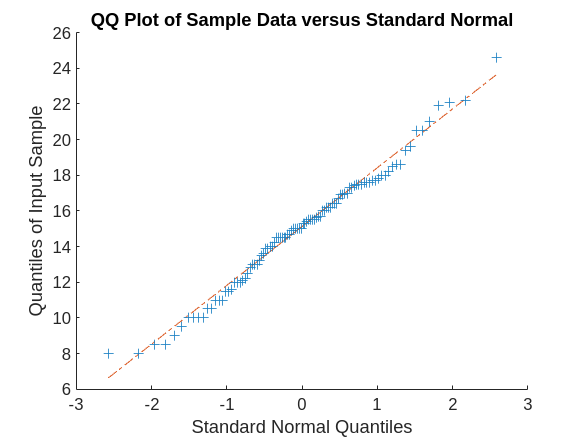

qqplot(Acceleration)

Try to fit a PDF on the histogram. (See also **dfittool**)

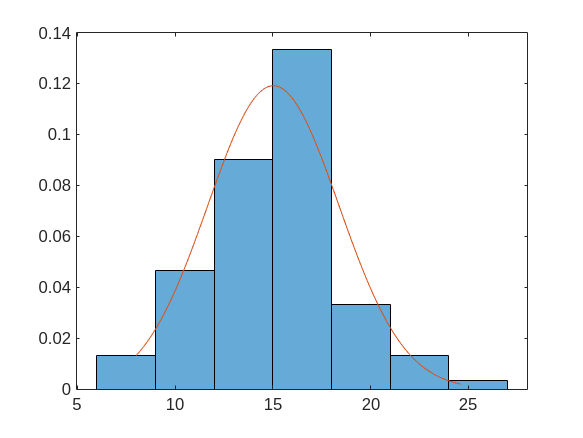

[pm pd] = normfit(Acceleration); % parameter estimations of the mean and std
xx = linspace(min(Acceleration),max(Acceleration));
histogram(Acceleration,'Normalization','pdf')
hold on;
plot(xx, normpdf(xx,pm,pd))
hold off;

Plot the Empirical CDF of log(Weight). Also fit an appropriate theoretical CDF.

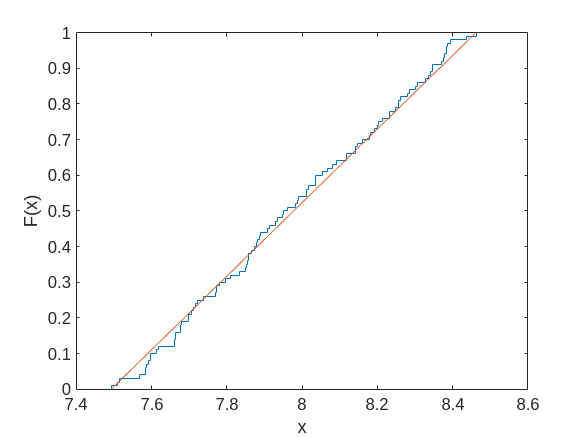

ecdf(log(Weight))
[a b] = unifit(log(Weight));
xx = linspace(a, b);
hold on;
plot(xx, unifcdf(xx,a,b))
hold off;

Make a frequency table from the 'Origin' of cars.

tbl = tabulate(Origin);
t = cell2table(tbl,'VariableNames', ...
    {'Value','Count','Percent'});
t.Value = categorical(t.Value)

t = 6×3 table
     Value     Count    Percent
    _______    _____    _______

    USA         69        69   
    France       4         4   
    Japan       15        15   
    Germany      9         9   
    Sweden       2         2   
    Italy        1         1   


Plot a barplot.

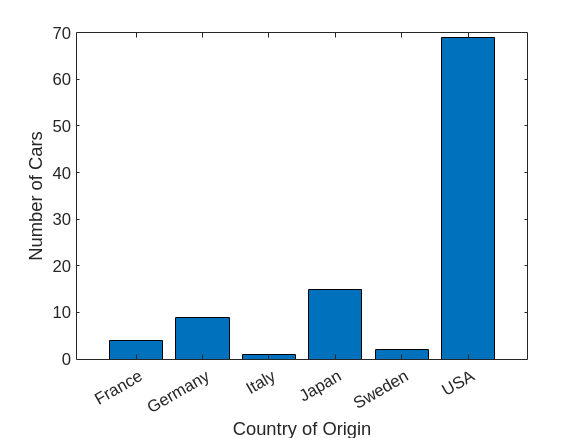

bar(t.Value,t.Count)
xlabel('Country of Origin')
ylabel('Number of Cars')